data = load('resultadosCSV_2mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*2e6)

T_buscado =      2.500000000000000e-07


T_buscado/50

ans =      5.000000000000000e-09


#### Separación de datos

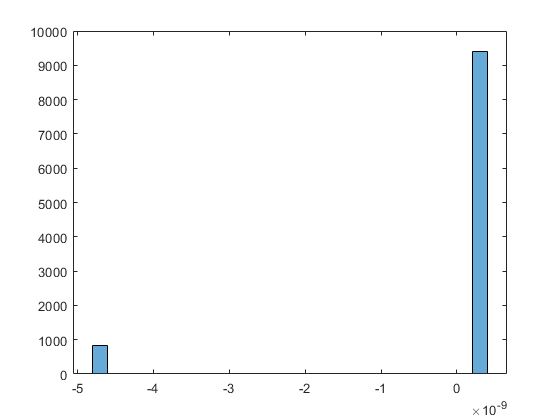

t_fino = (start)*tau_start - (stop)*tau_stop;
t = (coarse*T) + t_fino;
histogram(t_fino)   

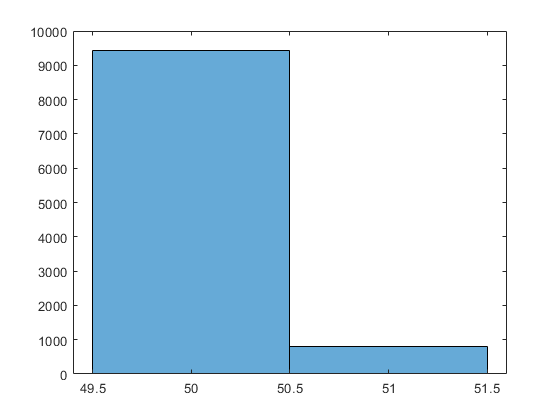

histogram(coarse)

sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado)

ans = '50 coarse son: 2.500000e-07 y lo buscado es: 2.500000e-07'

indices_50 = find(coarse==50);
indices_51 = find(coarse==51);

x = 1:1:10240

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


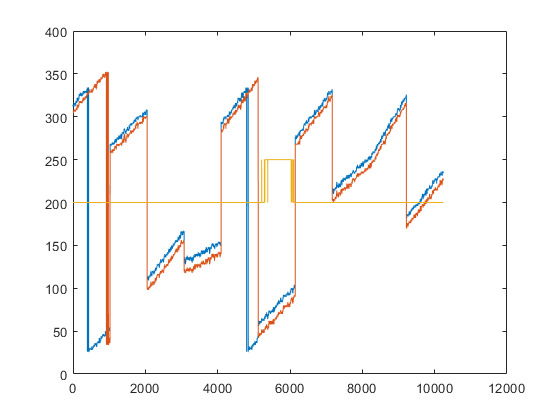

plot(x, start);
hold on;
plot(x, stop);
plot(x, 50*(coarse-50)+200)
hold off;

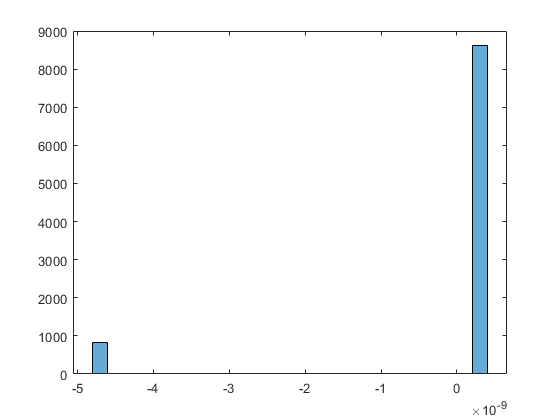


%Mediciones 50
clf;
fino_50 = t_fino(indices_50);
histogram(fino_50);

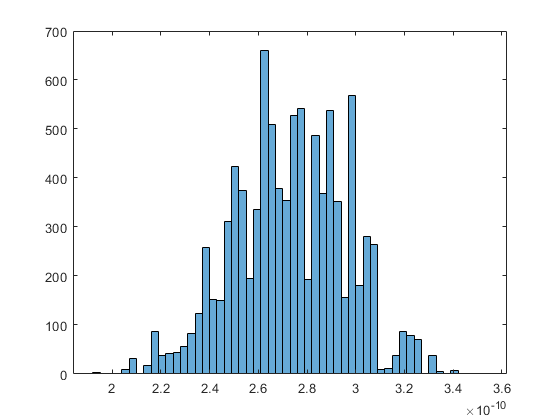

fino_50_buenas = fino_50(fino_50>0);
fino_50_malas = fino_50(fino_50<0);
histogram([fino_50_buenas; fino_50_malas+T])

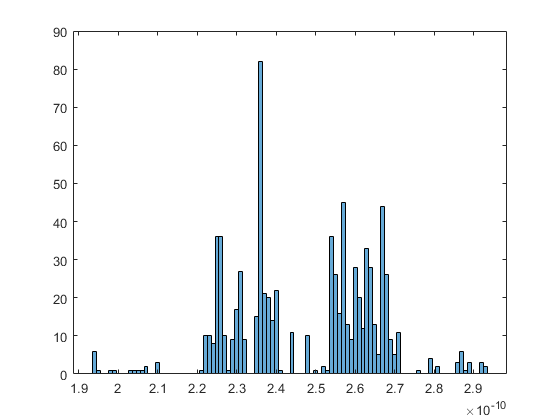



%%Mediciones 51
clf;
fino_51 = t_fino(indices_51);
histogram(fino_51, 100)

#### Export

clf;
y = [fino_50_malas+T; fino_50_buenas; fino_51];
presicion = std(y)

presicion =      2.391556002457789e-11


media     = mean(y)

media =      2.710478437499950e-10


coarse_correcto = 50;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_51, fino_50_malas+T, fino_50_buenas};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
length(fino_51)

ans =    796


length(fino_50_malas)

ans =    822


length(fino_50_buenas)

ans =         8622


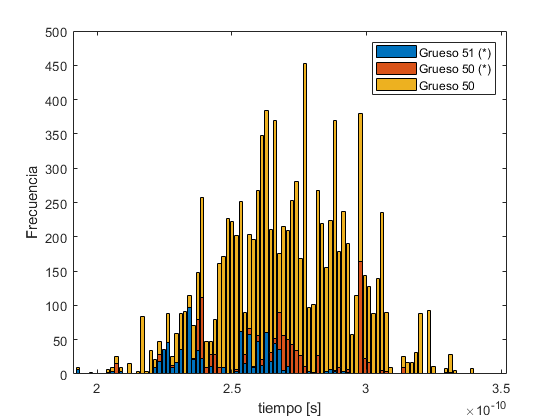

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({['Grueso 51 (*)'], 'Grueso 50 (*)', 'Grueso 50'});
exportgraphics(gcf,'histograma_2M.eps');


format long
T_buscado

T_buscado =      2.500000000000000e-07


Tiempo_final = 50*T + media

Tiempo_final =      2.502710478437500e-07


error = Tiempo_final - T_buscado

error =      2.710478437499812e-10


clear;
data = load('resultadosCSV_2m_2.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*2e6)

T_buscado =      2.500000000000000e-07


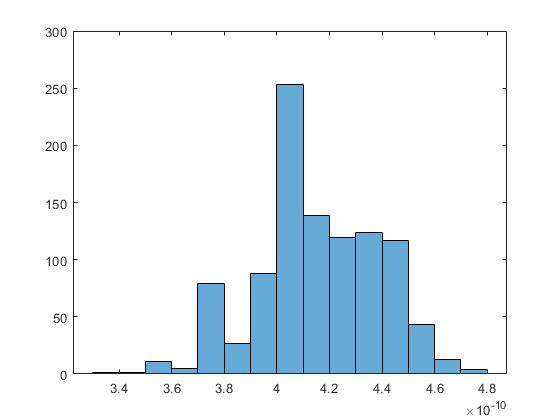

t_fino = (start-n_min_start)*tau_start - (stop-n_min_stop)*tau_stop;
t = (coarse*T) + t_fino;
histogram(t_fino)

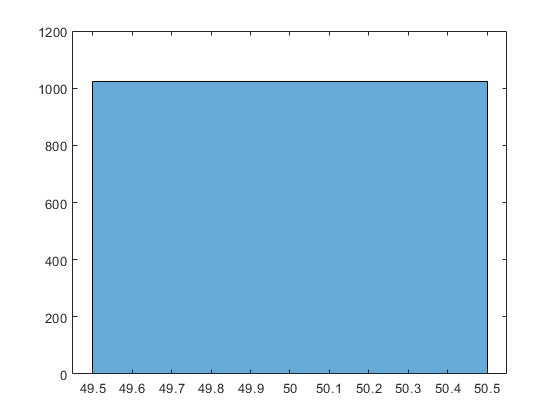

histogram(coarse)

sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado)

ans = '50 coarse son: 2.500000e-07 y lo buscado es: 2.500000e-07'

indices_50 = find(coarse==50);
indices_51 = find(coarse==51);

x = 1:1:1024

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


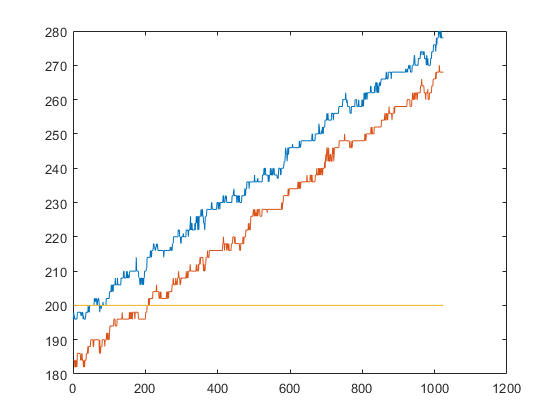

plot(x, start);
hold on;
plot(x, stop);
plot(x, 50*(coarse-50)+200)
hold off;


50*T

ans =      2.500000000000000e-07


%Mediciones 50
clf;
fino_50 = t_fino(indices_50);
histogram(fino_50);